clc;
clear variables;

mode = 0;   % 0: simulation mode / 1: real mode

## 텔로 이륙하기

if (mode>0)
    my_tello = ryze();
    takeoff(my_tello);
    pause(3);   % wait for stability
else 
    my_tello = 0;
end

## 영상 가져오기

if (mode>0)
    my_camera = camera(my_tello);
    img = snapshot(my_camera);
    %imwrite(img, 'snapshot.png');
else
    img = imread('snapshot.png');
end

## 붉은색 공 추적하기 - 공이 화면 중앙에 오도록 제어하기

drone move to 0.0, 0.1, 0.1
drone move to 0.0, 0.1, 0.0
drone move to 0.0, 0.1, 0.0
done


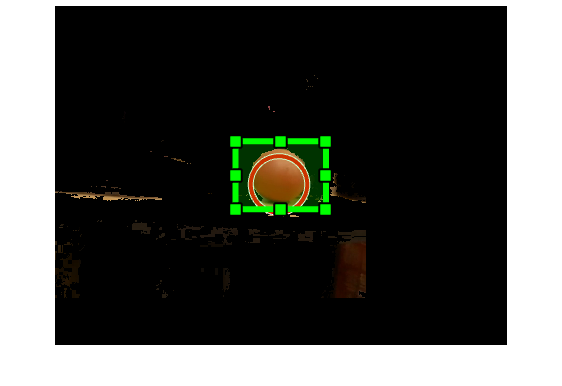

[height, width, channels] = size(img);
center = [width/2, height/2];
offset = [round(width/10), round(height/10)];

flag = true;
while(flag)
    [ball_pos, ball_radius] = FindRedBall(img);
    displace = (ball_pos - center);    
    [img, flag] = MoveAndSnap(mode, my_tello, img, displace, offset);
    drawrectangle('Position',[center-offset,offset*2],'Color',[0 1 0]);
    a = input('press enter');
end

## 텔로 착륙하기

if (mode>0)
    land(my_tello);
end
clear variables;